# **Orbital Mechanics of a Human Cannon**

*Authors: *Drew Pang and Omar Salih

## Question:

From planet Earth, what angle and speed should a person be launched at to hit the moon? Is it even possible to launch a human out of a cannon to hit the moon? This is something that everyone has thought of at least once in their lives. This is a design question that will be optimized and tested in the form of a model, in order to answer our question. The unintuitive nature of orbital physics makes this question interesting to not only us, but astrophysicists, daredevils, and astronauts. Of course, we will have more assumptions to further narrow the scope of our model. We will learn about the intricacies of orbital mechanics, and how complex the process of launching things into orbit truly is. 

## **Model:**

Our question will be answered based on a graph displaying the launch trajectory of the human over the course of a month. It also displays the locations of the Earth and the Moon. The two parameters being altered are the launch angle and the launch velocity of the human. Below we have the schematic diagram and the FBDs associated with our model:

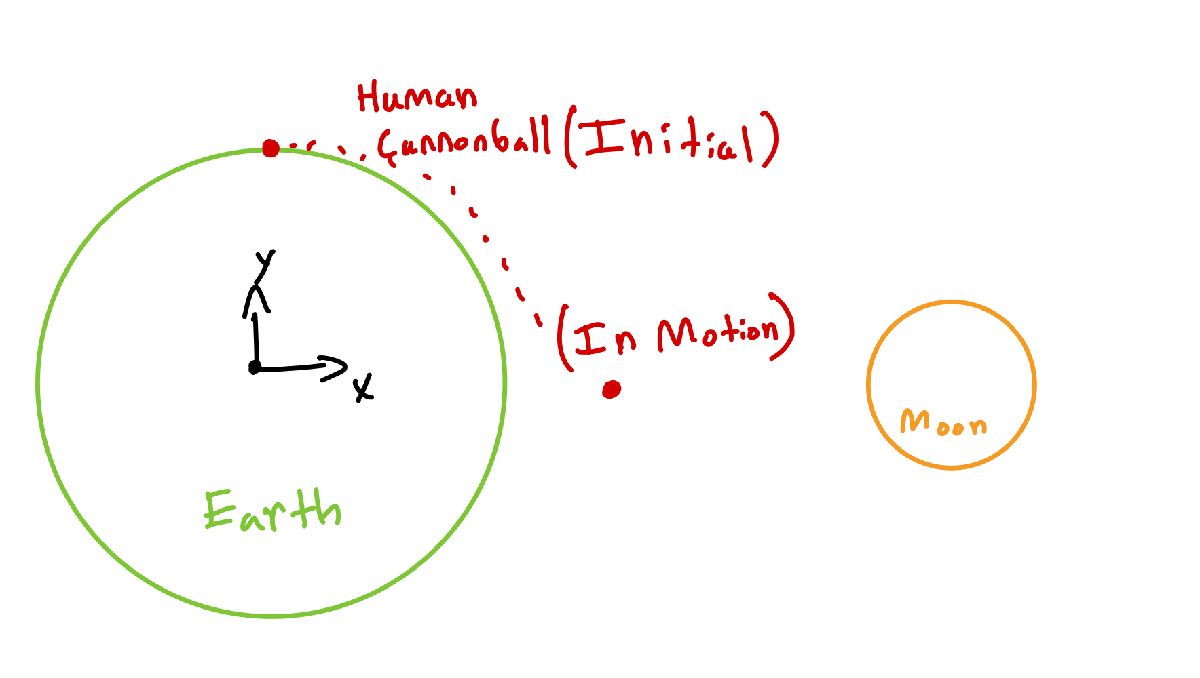

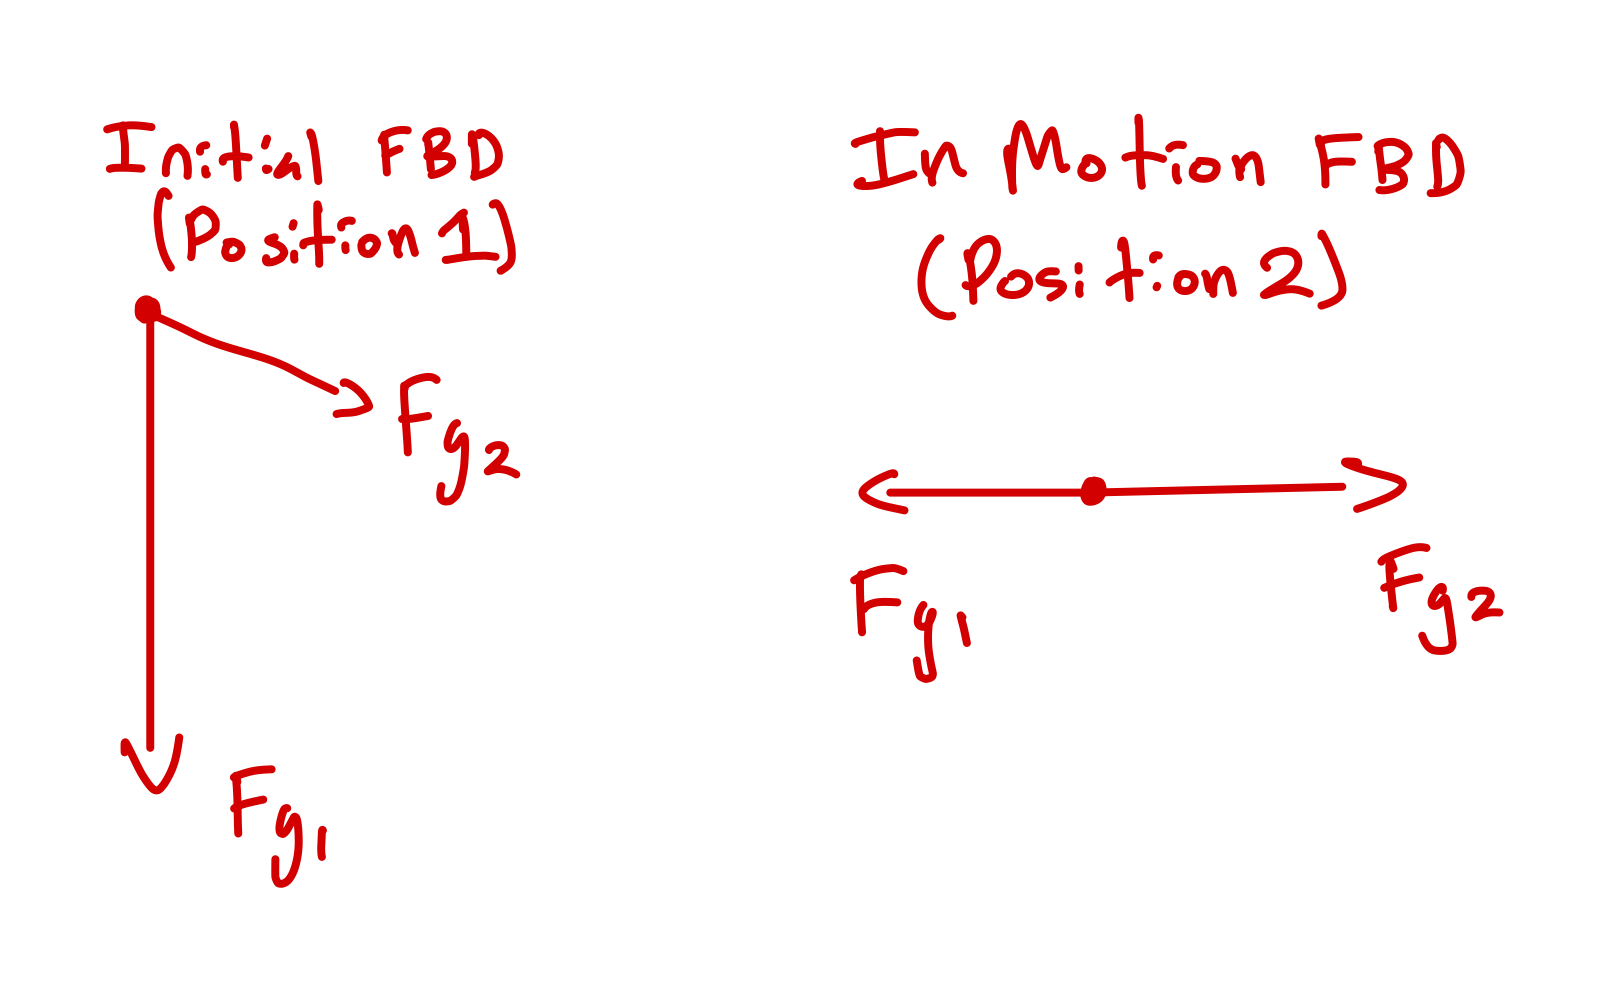

$F_{g1}$ = Force of gravity of the Earth

$F_{g2}$ = Force of gravity of the Moon

**Assumptions:**

For simplicities sake, the Earth and the Moon are stationary, since the model can get quite complex with an orbit. There’s also no air resistance within our model, because that would require us to have a ground launch and overcome the atmosphere. The Earth and Moon are perfect spheres to avoid collisions with irregular formations on the surfaces of these bodies. The human is a point-mass for the purpose of simplicity.

**Calculations**

Here is the mathematical representation of our model in the form of first and second-order ODEs:


$$\frac{d^2p}{dt^2} = \frac{Gm_1}{r_{1}^2}\hat{r_1}+\frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dv}{dt} = \frac{Gm_1}{r_{1}^2}\hat{r_1} + \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dp}{dt} = \hat{v}$$


$m_1$ = Mass of the Earth 

    % Should we include what the other values stand for?

$m_2$ = Mass of the Moon

$m_3
$ = Mass of the Human Cannonball

**Parameters**

The parameters in our model involve the launch angle and launch velocity of the human. In order to reach the moon, there has to be a specific launch velocity. For planet Earth, the escape velocity (disregarding atmospheric resistance) is about 11.2km/s, or 6.96 miles per second. This meant that we’d have to start our model launching the human at a speed of 11.2 km/s or faster. As for the launch angle, we’d be launching from an angle of 0° to 90°, because any angle outside this range would end up hitting the Earth’s surface. 

**Model**

Before attempting to optimize our system, we need to create a model that accurately calculates the position of a body shot off of the Earth. We created `body_2D_ode45() `to simulate our body in space. We can input some different values to simulate some different results. 

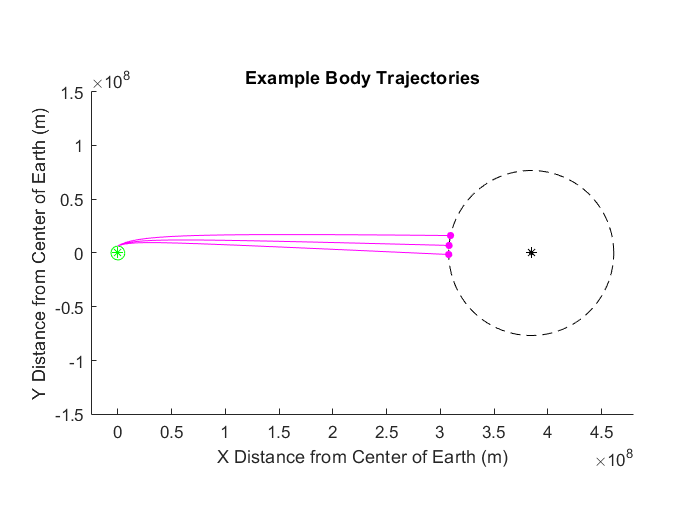

% Example body trajectories

% Plot Earth, Moon, and satelite orbit
plot_earth_moon()

% Plot multiple launch angles
launchAnglesAndVelocities = [25 12470; 30 11900; 35 11500];
for i = 1:3
    launchAngle = launchAnglesAndVelocities(i, 1);
    launchVelocity = launchAnglesAndVelocities(i, 2);
    [~, M] = body_2D_ode45(launchAngle, launchVelocity);
    plot(M(:,1), M(:,2),'m');
    plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
end

% Label graph
title('Example Body Trajectories')

As you can see, our model stops the simulation when the body gets within 75,000km of the Moon. We can now used this to optimize our model.

**Process**

Initially, our goal was to hit the moon directly, after several attempts testing various launch angles and velocities, we found it extremely difficult to hit the moon directly with multiple angles/velocities; there was only one set of angles and speeds that would hit the moon. We realized given the limitations of ode45 that the simulation wouldn’t stop when the moon was hit, because the timestep at that point was too long. We tried ode45, ode15s, ode89, and others, but still achieved the same result. Given this, we concluded that it would be more feasible of a model if we expanded the margin of error of our model. After doing that, we set up a parameter sweep from angles 1° to 80° and speeds from 10000 m/s to 16000 m/s.

## **Results:**

We now have a working model and can parameter sweep both the launch angle and launch velocity. 

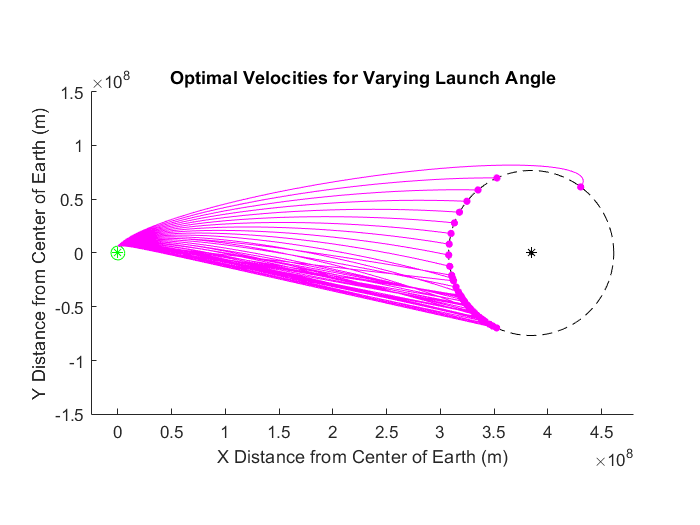

% Body trajectory examples

% Plot Earth, Moon, and satelite orbit
plot_earth_moon()

% Parameter sweep angle and velocity and only plot the most optimal
% velocity for each angle
optimizedVelocity = [];
for launchAngle = 0:1:80
    flag = 0;
    for launchVelocity = 10000:100:16000
        [T, M] = body_2D_ode45(launchAngle, launchVelocity);
        if T(end) ~= 60*60*24*7
            optimizedVelocity = [optimizedVelocity; launchAngle, launchVelocity];
            plot(M(:,1), M(:,2),'m');
            plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
            flag = 1;
        end
            if flag == 1
                break;
            end
    end 
end
title('Optimal Velocities for Varying Launch Angle')

In the graph above, the optimal, or smallest velocity is used and its trajectory is graphed. Our parameter sweep goes through values, then uses the event function in `body_2D_ode45() `to check if the body hits the Moon (the dotted circle). The optimal velocity is then saved in a matrix with the angle used named optimal velocity. 

With this optimalVelocity matrix, we can graph launch angle vs velocity below.  

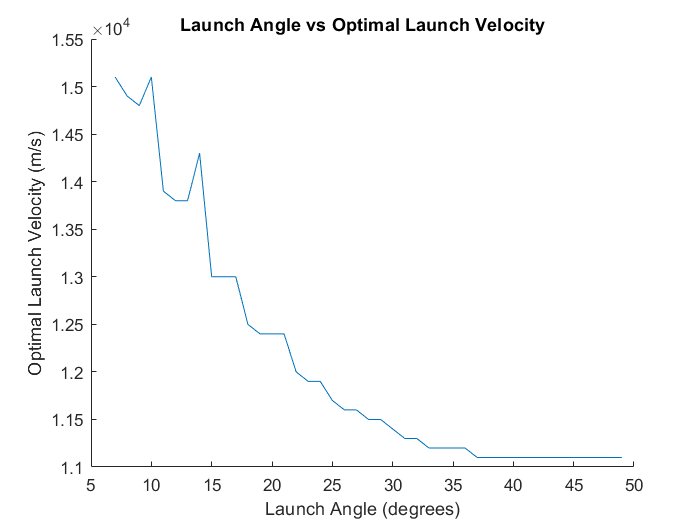

% Plot optimal launch
figure(2); clf; hold on;
plot(optimizedVelocity(:,1),optimizedVelocity(:,2))
xlabel('Launch Angle (degrees)'); ylabel('Optimal Launch Velocity (m/s)'); title('Launch Angle vs Optimal Launch Velocity');

**Verification**

In order to verify our model, we can look at the Launch Angle vs Optimal Launch Velocity graph. If we plot the terminal velocity of Earth of 11.2km/s, we get the following graph:

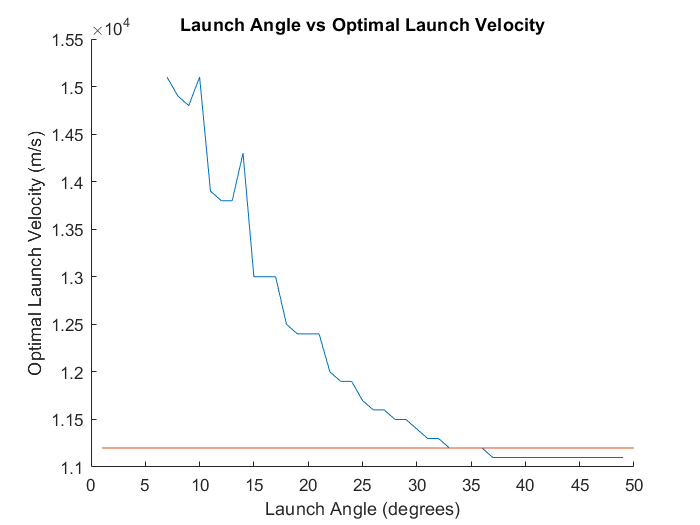

% Plot optimal launch
figure(2); clf; hold on;
plot(optimizedVelocity(:,1),optimizedVelocity(:,2))
xlabel('Launch Angle (degrees)'); ylabel('Optimal Launch Velocity (m/s)'); title('Launch Angle vs Optimal Launch Velocity');
% PLot line at 11.2km/s
y = 1.12*10^4 *ones(1,50);
plot(y)

As you can see, our optimal velocity stays above the terminal velocity line, except from the end. It may dip below it at the end, but in general our model adheres to the laws of physics. If we were to include more detail in our model, like air resistance on the Earth, our optimal velocity graph would likely stay above our terminal velocity line. 

## Interpretation

Given our results, we can first conclude that it is indeed possible to launch a human to the moon, as long as some assumptions are made. Our model sweeps through multiple values of angles and velocities in order to determine the most optimal angle and velocity for launch. We've concluded that the slowest speed required in order to hit the moon is a launch speed of __ at a launch angle of __ degrees. 

We think that the sets of answers that we've reached aren't the best, but given the limitations of ode and assumptions we've made, we think that the answers we've reached are valid. First of all, our margin of error creates a 'planet' that's larger than Jupiter. Jupiter has a radius of 69911 km, and the “Moon” has a radius of 76380 km, making our "Moon" the largest planet in our solar system. The reason we had to expand our margin of error to this degree is because of the time steps that ode takes. If you launch the human at a speed too quick, ode will think that there's a straight line and that the slope of the graph doesn't change often, therefore ode expands the increments of the time steps. Our event function requires the smaller steps in order to determine when the projectile hits the Moon, but currently, since the time steps are located before and after the moon, the event function doesn't stop the simulation and the projectile continues to fly past (or even through) the Moon.

Parameter sweeping finds values are very computationally taxing, therefore we weren’t able to get the most optimal values for velocities and angles since the velocities jumped in increments of 10 m/s, and the angles in 1-degree increments. Originally our model looked like the one below, but it took too long to run:

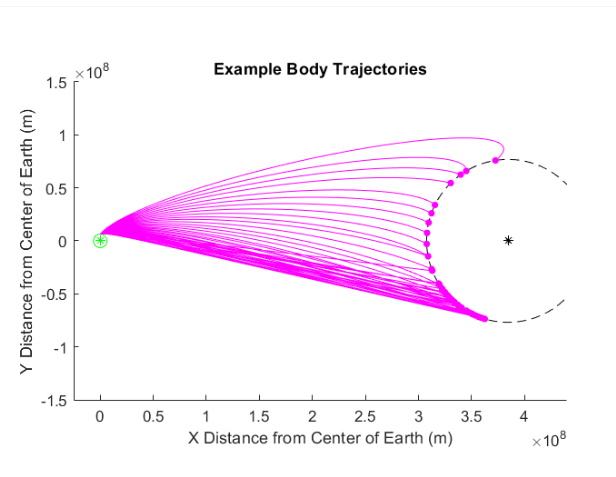

Our current model has velocities jumping in increments of 100 m/s, and the angles in 1-degree increments, which is much less optimized than our original.

Another limitation is the lack of an atmosphere in our model, which assumes no air resistance. This isn’t realistic because air resistance is a large factor when it comes to escape velocities and leaving the Earth’s atmosphere. Depending on the shape of the object launched and how much mass it has, this air drag can have a stronger or weaker effect.

If given more time for our model, we would attempt to circumvent the limitations of ODE by using a different time-step method, like Euler’s method, although that would also be computationally expensive. This would allow us to significantly decrease the margin of error, and make our model more accurate. We would also want to make our parameter sweep run at finer increments, in order to truly optimize the model and reach more accurate results than the ones we had to resort to. We would also like to include air resistance in our model, also to more accurately represent a launch from the Earth to the Moon.

## Resources

Howell, E. (2014, April 21). The Planets in Our Solar System in Order of Size. *Universe Today*. [https://www.universetoday.com/36649/planets-in-order-of-size/](https://www.universetoday.com/36649/planets-in-order-of-size/)

Lunar orbit. (2021). In *Wikipedia*. [https://en.wikipedia.org/w/index.php?title=Lunar_orbit&oldid=1043019297](https://en.wikipedia.org/w/index.php?title=Lunar_orbit&oldid=1043019297)